clc; clear;



MD = importdata("MegetData.txt");

CP = py.importlib.import_module("CoolProp.CoolProp");

# Behandlet data

P1 = find(MD.textdata(1,2:end) == "P1 Tryk")

P1 =     15


H1 = find(MD.textdata(1,2:end) == "P1 Enthalpy")

H1 =     16



P2 = find(MD.textdata(1,2:end) == "P2 Tryk")

P2 =     20


H2 = find(MD.textdata(1,2:end) == "P2 Enthalpy")

H2 =     21



P3 = find(MD.textdata(1,2:end) == "P3 Tryk")

P3 =     25


H3 = find(MD.textdata(1,2:end) == "P3 Enthalpy")

H3 =     26



P4 = find(MD.textdata(1,2:end) == "P4 Tryk")

P4 =     30


H4 = find(MD.textdata(1,2:end) == "P4 Enthalpy")

H4 =     31



start = 10;

p1 = MD.data(start:end, P1);
h1 = MD.data(start:end, H1);

p2 = MD.data(start:end, P2);
h2 = MD.data(start:end, H2);

p3 = MD.data(start:end, P3);
h3 = MD.data(start:end, H3);

p4 = MD.data(start:end, P4);
h4 = MD.data(start:end, H4);

h4(500:850)'

ans =                 234.736032                234.736032                234.736032                234.699267                234.699267                234.711524                234.711524                234.711524                234.662483                234.662483                234.699267                234.699267                234.687008                234.687008                234.687008                234.687008                234.687008                234.674747                234.674747                234.625681                234.625681                234.687008                234.687008                234.687008                234.662483                234.662483                234.674747                234.674747                234.662483                234.662483                234.662483                234.650218                234.650218                234.650218                234.650218                234.625681                234.625681                234.625681      


ps = MD.data(start:end, [P1,P2,P3,P4]);
hs = MD.data(start:end, [H1 H2 H3 H4]);

mean_ps = max(ps)

mean_ps =                   2.346939                  8.135958                  8.135958                  2.346939


mean_hs = max(hs)

mean_hs =                 395.091481                440.041789                244.507281                244.507281



max([h1 h2 h3 h4])

ans =                 395.091481                440.041789                244.507281                244.507281





hlin1 = linspace(mean_hs(1),mean_hs(2));
hlin2 = linspace(mean_hs(2),mean_hs(3));
hlin3 = linspace(mean_hs(3),mean_hs(4));
hlin4 = linspace(mean_hs(4),mean_hs(1));
hs_test = [hlin1,hlin2,hlin3,hlin4];

plin1 = linspace(mean_ps(1),mean_ps(2));
plin2 = linspace(mean_ps(2),mean_ps(3));
plin3 = linspace(mean_ps(3),mean_ps(4));
plin4 = linspace(mean_ps(4),mean_ps(1));
pps_test = [plin1,plin2,plin3,plin4];


# Temps

Tbrine = find(MD.textdata(1,2:end) == "Brinetemperatur")

Tbrine =      4


Trum = find(MD.textdata(1,2:end) == "Rumtemperatur")

Trum =      2




Tbrine = mean(MD.data(start:end-1, Tbrine))

Tbrine =          -9.92027095284395


Trum = mean(MD.data(start:end,Trum))

Trum =           24.0529084183673



T_komp = find(MD.textdata(1,2:end) == "Temperaturen efter fordamper")

T_komp =      6


T_kond = find(MD.textdata(1,2:end) == "Temperatur efter kompressor")

T_kond =     10


T_EPV = find(MD.textdata(1,2:end) == "Temperatur efter kondensator ")

T_EPV =     11


T_fordamp = find(MD.textdata(1,2:end) == "Temperatur efter EPV")

T_fordamp =      9



T1 = min(MD.data(start:end-start, T_komp))

T1 =                 -14.569843


T2 = min(MD.data(start:end-start, T_kond))

T2 =                  24.620118


T3 = min(MD.data(start:end-start, T_EPV))

T3 =                   23.83616


T4 = min(MD.data(start:end-start, T_fordamp))

T4 =                 -27.203071



fast = MD.data(start:end-start, T_fordamp);

min(fast(500:895))

ans =                 -21.368652


max(fast(500:895))

ans =                  -18.47426


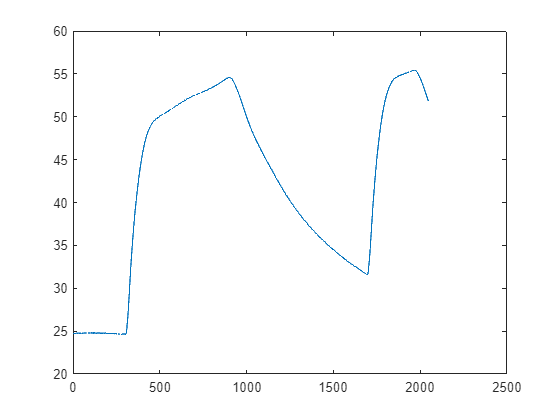


figure
plot(MD.data(start:end-start, T_kond))

Tbrine = find(MD.textdata(1,2:end) == "Brinetemperatur")

Tbrine =      4



ind = 500:895;
Tbrine = MD.data(start:end-10, Tbrine)

Tbrine =                  -9.511527
                 -9.503681
                 -9.509384
                 -9.506844
                 -9.499626
                  -9.49246
                 -9.501594
                 -9.511144
                 -9.513364
                 -9.486249


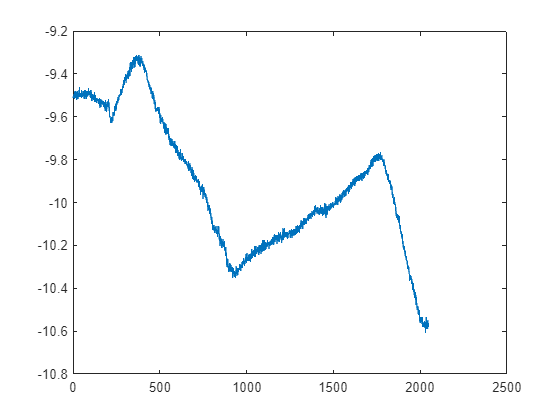


figure
plot(Tbrine)

# Teoretisk data

% Kølemiddel
ps = 100;
Tfrys = 0;
Tkog = 1200;
middel = "R134a";

% for R134a
Pmin = CP.PropsSI("P","T",170, "Q", 0, middel)

Pmin =           396.167894782514


Pmax = CP.PropsSI("P","T", 374, "Q", 1, middel)

Pmax =           4042129.37699199


Plin = linspace(Pmin, Pmax, ps);


Tsat_l = zeros(size(Plin));

for i = 1:ps-1
    Tsat_l(i) = CP.PropsSI("T", "P", Plin(i), "Q", 0, middel);
end

hl = zeros(size(Plin));
hg = zeros(size(Plin));
sl = zeros(size(Plin));
sg = zeros(size(Plin));

for j = 1:ps-1
    hl(j) = CP.PropsSI("H","P",Plin(j), "Q", 0, middel);
    hg(j) = CP.PropsSI("H","P",Plin(j), "Q", 1, middel);
    sl(j) = CP.PropsSI("S","P",Plin(j), "Q", 0, middel);
    sg(j) = CP.PropsSI("S","P",Plin(j), "Q", 1, middel);
end


% Uden tab

h1 = 389428;
p1 = 1.33e5;

h2 = 467171;
p2 = 8.868*1e5;

h3 = 241463;
p3 = p2;

h4 = h3;
p4 = p1;

%til plot

hlin1 = linspace(h1,h2,ps-1);
hlin2 = linspace(h2,h3,ps-1);
hlin3 = linspace(h3,h4,ps-1);
hlin4 = linspace(h4,h1,ps-1);
hs = [hlin1,hlin2,hlin3,hlin4];

plin1 = linspace(p1,p2,ps-1);
plin2 = linspace(p2,p3,ps-1);
plin3 = linspace(p3,p4,ps-1);
plin4 = linspace(p4,p1,ps-1);
pps = [plin1,plin2,plin3,plin4]/1e5;

Tr134a = zeros(size(pps));


for k = 1:length(pps)
    Tr134a(k) = CP.PropsSI("T","H",hs(k),"P",pps(k)*1e5, middel);
end
Tr134a;
Trs = Tr134a-273.15;


% Fra opgave

htab1 = 389428;
ptab1 = 1.33e5;

htab2 = 467171;
ptab2 = 8.868e5;

htab3 = 236622;
ptab3 = 8.068e5;

htab4 = htab3;
ptab4 = 1.65e5;

%til plot

hlintab1 = linspace(htab1,htab2,ps-1);
hlintab2 = linspace(htab2,htab3,ps-1);
hlintab3 = linspace(htab3,htab4,ps-1);
hlintab4 = linspace(htab4,htab1,ps-1);
hs_tab = [hlintab1,hlintab2,hlintab3,hlintab4];

plintab1 = linspace(ptab1,ptab2,ps-1);
plintab2 = linspace(ptab2,ptab3,ps-1);
plintab3 = linspace(ptab3,ptab4,ps-1);
plintab4 = linspace(ptab4,ptab1,ps-1);
pps_tab = [plintab1,plintab2,plintab3,plintab4]/1e5;

Tr134a_tab = zeros(size(pps));


for k = 1:length(pps)
    Tr134a_tab(k) = CP.PropsSI("T","H",hs_tab(k),"P",pps_tab(k)*1e5, middel);
end
Tr134a;
Trs_tab = Tr134a_tab-273.15;




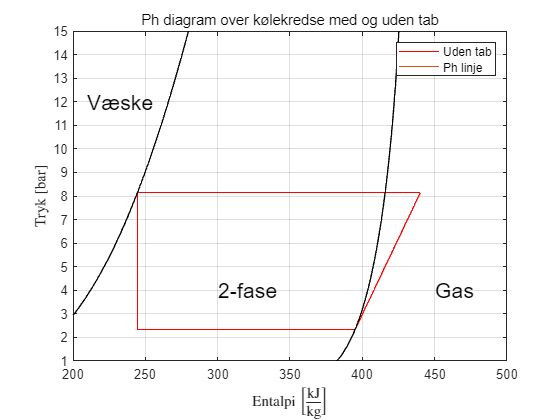


figure

% Kølekreds uden tab
plot(hs_test,pps_test,"r")

xlim([2,5]*1e2)
ylim([1,15])
yticks(1:1:15)


grid("on")

hold on
plot(hs, pps)


% PH diagram (ikke log)
plot(hl(1,1:end-1)/1e3,Plin(1,1:end-1)/1e5,"k")
plot(hg(1,1:end-1)/1e3, Plin(1,1:end-1)/1e5,"k")

title("Ph diagram over kølekredse med og uden tab","FontWeight","normal")
ylabel("Tryk [bar]","Interpreter","latex")
xlabel("Entalpi $\left[\mathrm{\frac{kJ}{kg}}\right]$","Interpreter","latex")

text(450, 4,"Gas","FontSize",16)
text(300, 4,"2-fase","FontSize",16)
text(210, 12,"Væske","FontSize",16)

legend("Uden tab","Ph linje","location","northeast")

hold off

exportgraphics(gcf,"EntalpiSlush.png")

## Brine

ind = 10;



MD_Tbrine = find(MD.textdata(1,2:end) == "Brinetemperatur")

MD_Tbrine =      4


MD_Tbrine = MD.data(ind:end-ind, MD_Tbrine);







ind_plot = find(max(MD_Tbrine) == MD_Tbrine)

ind_plot =    365



xs = length(MD_Tbrine(ind:end))*2*0.142/60

xs =           9.65126666666666


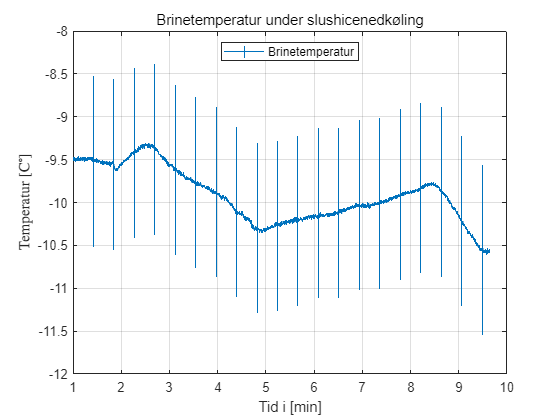


xlin = linspace(1,xs, length(MD_Tbrine(ind:end)));


lps = length(xlin);

errlin = zeros(1,lps);

fejl = 0.9798;

for i = 1:lps
    if mod(i,100) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end



figure

errorbar(xlin, MD_Tbrine(ind:end),errlin,"CapSize",0)

ylabel("Temperatur [C$^\circ$]",Interpreter="latex")


grid("on")
legend("Brinetemperatur","Location","north")
title("Brinetemperatur under slushicenedkøling","FontWeight","normal")
xlabel("Tid i [min]")



exportgraphics(gcf,"BrineTempSlush.png")

## Tryk

MD_lavtryk = find(MD.textdata(1,2:end) == "Tryk lav")

MD_lavtryk =     13


MD_hojtryk = find(MD.textdata(1,2:end) == "Tryk høj")

MD_hojtryk =     12


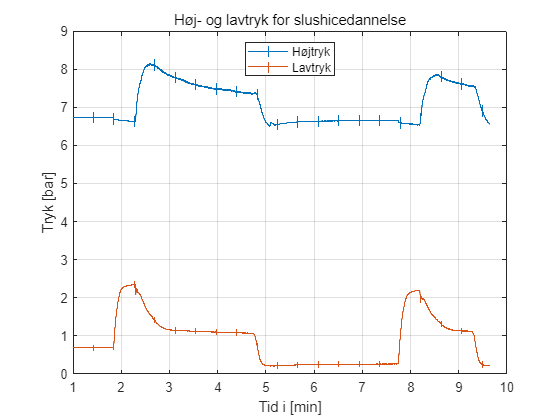


MD_lavtryk = MD.data(ind:end-19, MD_lavtryk) +1;
MD_hojtryk = MD.data(ind:end-19, MD_hojtryk) +1;

lps = length(xlin);

errlin_hoj = zeros(1,lps);
errlin_lav = zeros(1,lps);

fejlhoj = 0.008*20;
fejllav = 0.008*12;

for i = 1:lps
    if mod(i,100) == 0
        errlin_hoj(i) = fejlhoj;
        errlin_lav(i) = fejllav;
    else
        errlin_hoj(i) = 0;
        errlin_lav(i) = 0;
    end
    
end

figure


errorbar(xlin, MD_hojtryk, errlin_hoj,"CapSize",0)
ylabel("Tryk [bar]")

hold on


errorbar(xlin, MD_lavtryk, errlin_lav,"CapSize",0)
hold off


grid("on")
legend("Højtryk","Lavtryk","Location","north")
title("Høj- og lavtryk for slushicedannelse","FontWeight","normal")
xlabel("Tid i [min]")

exportgraphics(gcf, "HojLavTrykSlush.png")

## Kondensator temperatur


T_kond = find(MD.textdata(1,2:end) == "Temperatur efter kompressor")

T_kond =     10


T_EPV = find(MD.textdata(1,2:end) == "Temperatur efter kondensator ")

T_EPV =     11


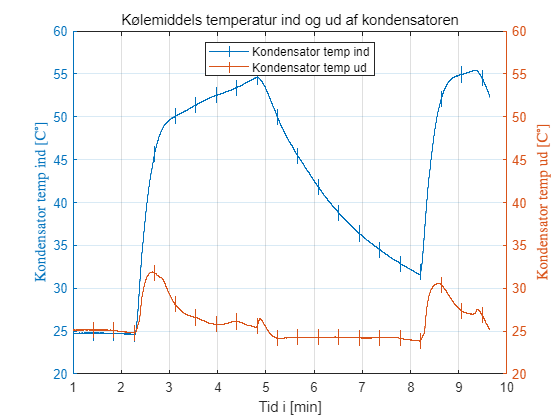




T2 = MD.data(start:end-start-9, T_kond);
T3 = MD.data(start:end-start-9, T_EPV);

lps = length(xlin);

errlin = zeros(1,lps);

fejl = 0.9798;

for i = 1:lps
    if mod(i,100) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end

figure

yyaxis left
errorbar(xlin, T2,errlin,"CapSize",0)
ylabel("Kondensator temp ind [C$^\circ$]", "Interpreter","latex")

ylim([20,60])

yyaxis right
errorbar(xlin, T3,errlin,"CapSize",0)
ylabel("Kondensator temp ud [C$^\circ$]", "Interpreter","latex")
ylim([20,60])


grid("on")
legend("Kondensator temp ind","Kondensator temp ud","Location","north")
title("Kølemiddels temperatur ind og ud af kondensatoren","FontWeight","normal")
xlabel("Tid i [min]")


exportgraphics(gcf,"KondTempsSlush.png")

## Fordamper temperatur

T_komp = find(MD.textdata(1,2:end) == "Temperaturen efter fordamper")

T_komp =      6



T_fordamp = find(MD.textdata(1,2:end) == "Temperatur efter EPV")

T_fordamp =      9


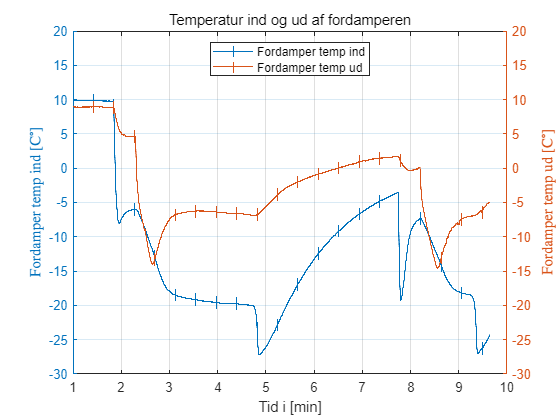


T1 = MD.data(start:end-start-9, T_komp);
T4 = MD.data(start:end-start-9, T_fordamp);

errlin = zeros(1,lps);

fejl = 0.9798;

for i = 1:lps
    if mod(i,100) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end


figure

yyaxis left
errorbar(xlin, T4,errlin,"CapSize",0)
ylabel("Fordamper temp ind [C$^\circ$]", "Interpreter","latex")

ylim([-30,20])

yyaxis right
errorbar(xlin, T1,errlin,"CapSize",0)
ylabel("Fordamper temp ud [C$^\circ$]", "Interpreter","latex")

ylim([-30,20])

grid("on")
legend("Fordamper temp ind","Fordamper temp ud","Location","north")
title("Temperatur ind og ud af fordamperen","FontWeight","normal")
xlabel("Tid i [min]")

exportgraphics(gcf,"FordampTempsSlush.png")

## Motortemperatur

MD_motortemp = find(MD.textdata(1,2:end) == "Motortemperatur");

MD_motortemp = MD.data(ind:end-19, MD_motortemp);

errlin = zeros(1,lps);

fejl = 0.9798;

for i = 1:lps
    if mod(i,100) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end

errlin

errlin =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


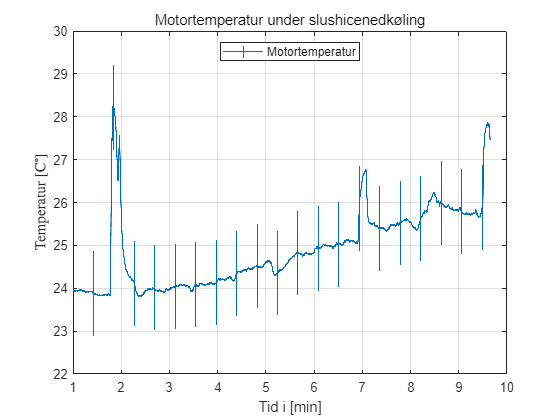


figure
errorbar(xlin, MD_motortemp, errlin,"CapSize",0)



ylabel("Temperatur [C$^\circ$]",Interpreter="latex")


grid("on")
legend("Motortemperatur","Location","north")
title("Motortemperatur under slushicenedkøling","FontWeight","normal")
xlabel("Tid i [min]")

exportgraphics(gcf,"MotorTempsSlush.png")

## Slushicetemperatur

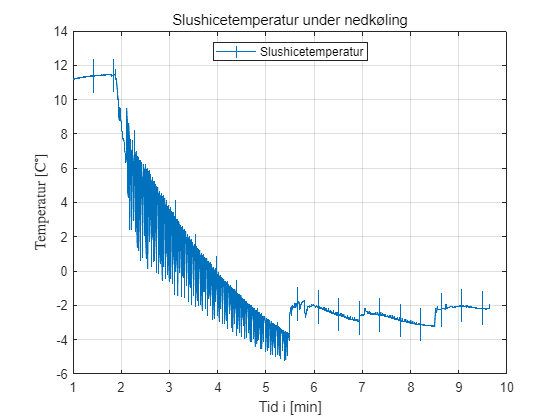

MD_slushtemp = find(MD.textdata(1,2:end) == "Slush Ice temperatur");

MD_slushtemp = MD.data(ind:end-19, MD_slushtemp);

errlin = zeros(1,lps);

fejl = 0.9798;

for i = 1:lps
    if mod(i,100) == 0
        errlin(i) = 1;
    else
        errlin(i) = 0;
    end
    
end

figure
errorbar(xlin, MD_slushtemp,errlin,"CapSize",0)

ylabel("Temperatur [C$^\circ$]",Interpreter="latex")


grid("on")
legend("Slushicetemperatur","Location","north")
title("Slushicetemperatur under nedkøling","FontWeight","normal")
xlabel("Tid i [min]")




exportgraphics(gcf,"SlushTempsSlush.png")

t = linspace(0,10,length(xlin));

fun_test = 21*exp(-0.34*t) - 10;
fun_teo = 21*exp(-0.48*t) - 10;

length(xlin(1:find(MD_slushtemp == min(MD_slushtemp))))

ans =         1033



find(MD_slushtemp == max(MD_slushtemp))

ans =    209


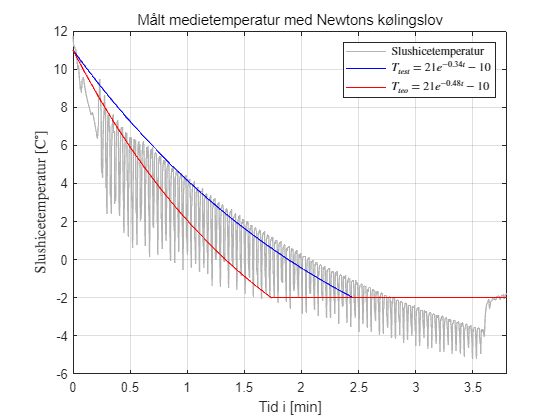




for i = 1:length(fun_teo)
    if fun_teo(i) > -2
        fteo(i) = fun_teo(i);
        
    else
        fteo(i) = -2;
       
    end

    if fun_test(i) > -2
        
        ftest(i) = fun_test(i);
    else
        
        ftest(i) = -2;
    end
end



figure

plot(xlin(1:find(MD_slushtemp == min(MD_slushtemp)))-1, MD_slushtemp(209:(1033+208)),"Color",[0.70,0.700,0.700])


hold on
plot(xlin-1,ftest,"b")
plot(xlin-1,fteo,"r")
grid()
hold off

xlim([0,3.8])



title("Målt medietemperatur med Newtons kølingslov","FontWeight","normal")
ylabel("Slushicetemperatur [C$^\circ$]","Interpreter","latex")
xlabel("Tid i [min]")

legend("Slushicetemperatur","$T_{test} = 21e^{-0.34t} - 10$","$T_{teo} = 21e^{-0.48t} - 10$","location","northeast","Interpreter","latex")


exportgraphics(gcf,"NewtonsKolelov.png")